# Cropping Drops for ML Training/ Classification

**Aim: **prepare images for machine learning classification model. 

**Summary:** given a user-defined input video, individual frames will be extracted and pre-processed to obtain information on the centroid and bounding boxes. 

Each detected ROI (defined by bounding boxes) will be cropped out and saved into a new folder. The ROIs will also be cropped as a square image of a unform, user-defined size. 

**Associated data:**** SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi**

**Associated function files: **

-  *extractVidFrames.m*

- *Process4Crop.m     *

- *imgCrop.m *

**Log: **

**27-Jan-2021; SWC**. Completed code. Tested on:

1) SO5cSt 16uL_15 uL TRITON_0.5 mM 034.avi ---- testcrop003

2) SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi --- testcrop001

**28-Jan-2021; SWC.** Writeup comments on code. Add code to process multiple videos automatically

**03-Feb-2021; SWC.** Tidy notes and commite to github.

clear all 
close all 
clc

##  1) Load Video

vid_file_name = 'SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi'; %<-------- user-defined input!!
vid = VideoReader(vid_file_name); %read video 
% make sure video is in same path as codes!!!
totframes = vid.NumFrames %check total num of frames in video

totframes = 1434

## 2) Background Generation - Use Median of Frames

n = 200;    % number of frames to use for background generation  <-------- user-defined input!!
idx = round(linspace(1,totframes,n)); %vector of index of frame number to be extracted

frameMat = []; 

% for loop to create matrix of frames - for generating background image
for i=1:numel(idx)
    frame = read(vid,idx(i)); 
    frameMat = cat(3,frameMat,frame);
end

tic
med_pix = median(frameMat,3); %compute median of each pixel across all frames in matrix
toc

Elapsed time is 1.793785 seconds.


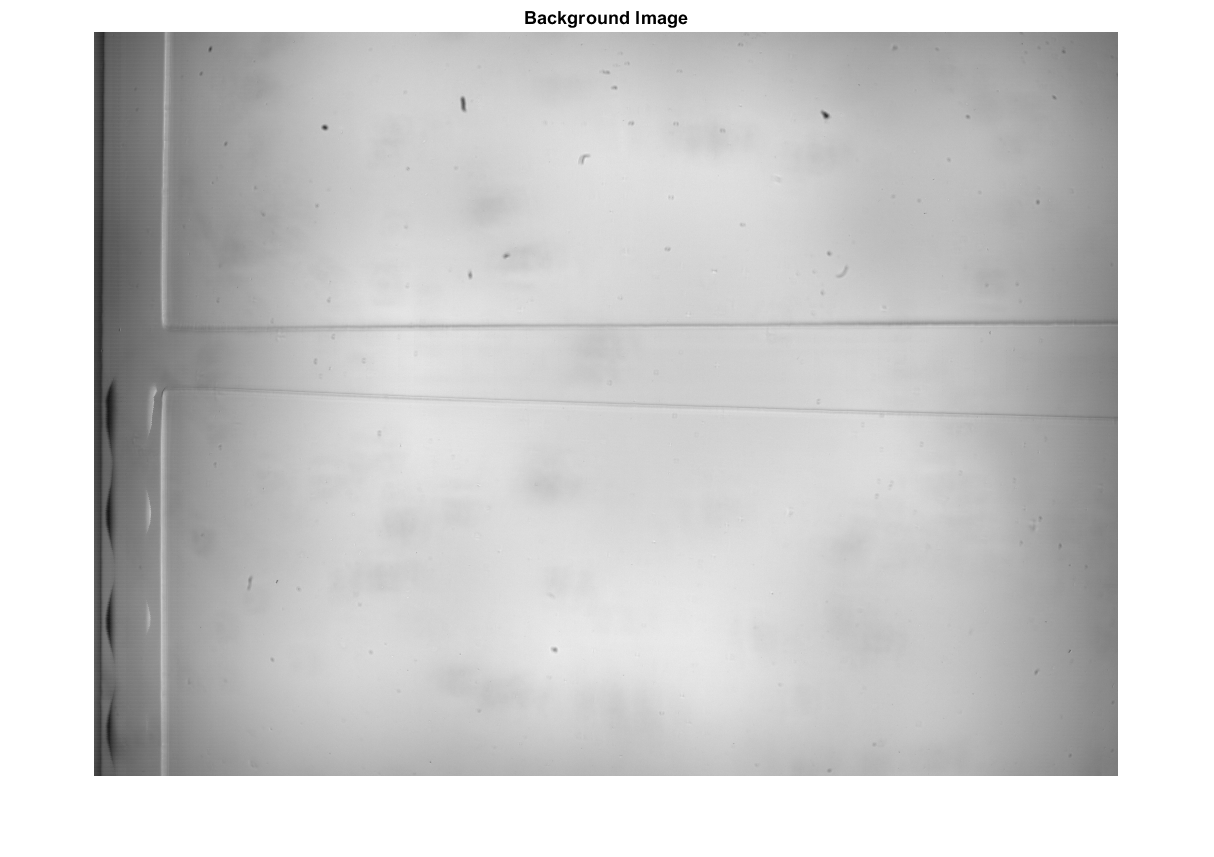


%show generated background 
imshow(med_pix); title("Background Image")

## 3) Extract Video Frames & Save in Temporary Folder

**Accompanying function file: ***extractVidFrames.m*

- Create temporary folder to store files

mkdir test001 % create new sub-folder  <-------- user-defined input!! (how you would like it to be called, can be anything)
addpath test001 % enable access to subfolder <-------- user-defined input!!

- Define user inputs for function

num_frames = totframes; % number of frames to extract from video <-------- user-defined input!!
file_path = 'test001\'; %folder to save images in <-------- user-defined input!!

- call function

extractVidFrames(vid_file_name, num_frames, file_path); %extracted video frames saved in temporary subfolder

## 4) Crop & Save Regions of Interest (ROIs)

**Accompanying function file(s): ***Process4Crop.m     &   imgCrop.m                                   *

- create subfolder to store cropped images

mkdir testcrop001 % <-------- user-defined input!! (how you would like it to be called, can be anything)
addpath testcrop001 %enable access to subfolder <-------- user-defined input!!


- inputs for Proces4Crop function 

temp_folder = dir('test001\*.jpg');  % access individual image frames<-------- user-defined input!!

bg = med_pix; %background image - generated earlier
t = 0.2; %treshold value  <-------- user-defined input!!

minArea = 1000; % <-------- user-defined input!!
% noise removal: drops less than this area will be excluded 

leadEdge = 140; % <-------- user-defined input!!
% so any objects positioned at x<140 will not be cropped. Thus, only focuses on
% drops along main flow channel

crop_file_path = 'testcrop001\'; %folder to save cropped images in 


- loop through each frame in subfolder

tic

for i = 1:numel(temp_folder)
    filename = temp_folder(i).name;
    img = imread(filename); 
    
    %extract information on Bounding boxes
    roiBbox = Process4Crop(img, bg, t, minArea, leadEdge); 
        
    %use bounding box coordinates to crop image 
    imgCrop(img, roiBbox, [128 128], crop_file_path,i);
    
end

toc

Elapsed time is 344.712277 seconds.
